# Set Options for Hexadecimal and Binary Numbers

The `readtable` function automatically detects hexadecimal and binary numbers with the `0x` and `0b` prefixes. To import such numbers when they do not have prefixes, use an import options object.

Create an import options object for the file `hexAndBinary.txt`. Its third column has hexadecimal numbers without the `0x` prefix.

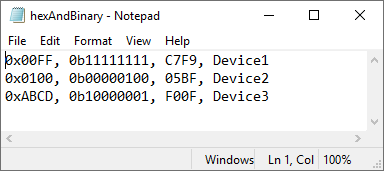

opts = detectImportOptions('hexAndBinary.txt')

To specify that the third column should be imported as hexadecimal values, despite the lack of a prefix, use the `setvaropts` function. Set the variable type of the third variable to `int32`. Set the number system for importing the third column to `hex`.

opts = setvaropts(opts,3,'NumberSystem','hex','Type','int32')

Read the file and import the first three columns as numeric values. The `readtable` function automatically detects that the first and second columns contain hexadecimal and binary values. The import options object specifies that the third column also contains hexadecimal values.

T = readtable('hexAndBinary.txt',opts)

*Copyright 2019 The MathWorks, Inc.*